## b) Kirchoff Solver and Network Preparation

Clear the workspace, set input parameters

clear; close all; more off

% define the size of the grid
n = 10;


numgrid numbers the grid points in a square with n+2 being the number of nodes of each side to make a side length n.

delsq creates a grid from the numbered grid points.

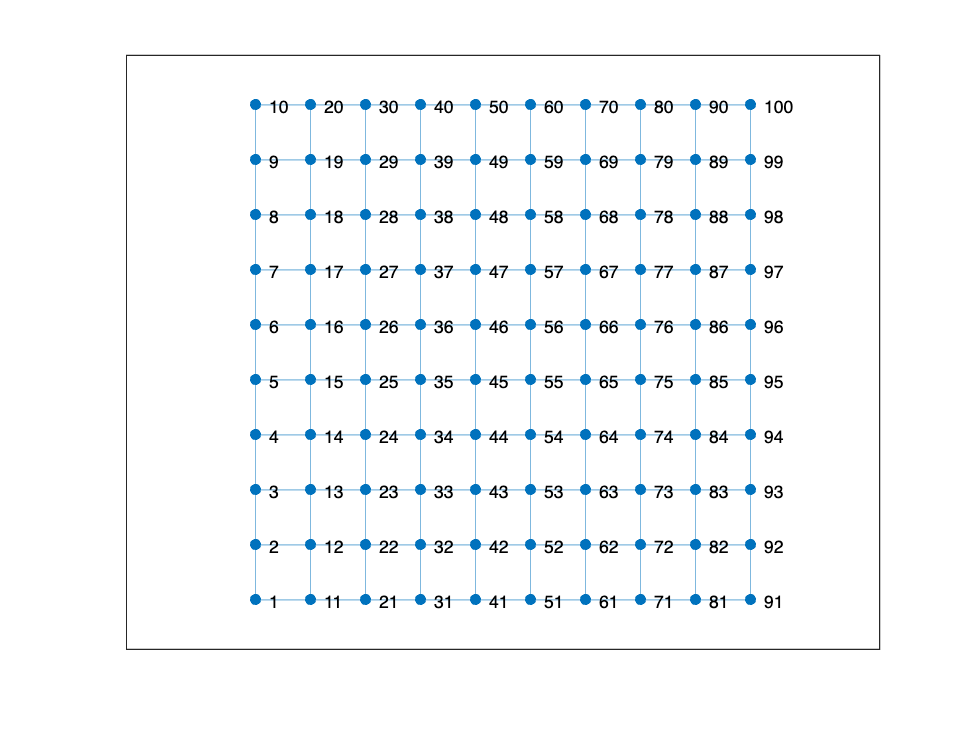

grid = delsq(numgrid('S',n+2));

% the graph function then creates a graph object (with nodes and edges)
% from the grid
ngraph = graph(grid,'omitselfloops');

% plot the graph
h = plot(ngraph);

% the data points need to be rounded to nearest integer so that the grid is
% straight
h.XData = floor((0:n^2-1)/n);
h.YData = rem((0:n^2-1), n);

axis equal

Calculate the positions of all nodes and the edges

% position of the nodes
x = h.XData;
y = h.YData;

% define edges st (graph object Edges outputs a table of edges and weights
% - we don't need the weights
st = table2array(ngraph.Edges);
st(:,3) = [];


Set Edge weights/resistances all as 1 since they are the same length

r = ones(length(st),1);

Create listAnode and listCnode (as starting node and ending node)

listAnode = [1];
listCnode = [n^2];

Call the solver, record solve time

tic;
[X,V]=KirchoffSolve(st,r,listAnode,listCnode);

____________________________________________________________
   Diagnostic Information

Number of variables: 182

 
Number of linear inequality constraints:    0
Number of linear equality constraints:      102
Number of lower bound constraints:          0
Number of upper bound constraints:          0

Algorithm selected
   interior-point-convex


____________________________________________________________
   End diagnostic information

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0    9.000000e+01   1.000000e+00   9.778500e-01     0.000000e+00  
    1    1.505835e+00   4.440892e-16   1.665335e-16     0.000000e+00  

Optimization completed: The relative dual feasibility, 1.665335e-16,
is less than options.OptimalityTolerance = 1.000000e-08, the 

t = toc

t = 0.2015

The voltage drop is the effective resistance of the network as the input current is 1. (V = IR)

Vdrop = V(listCnode(1))-V(listAnode(1))

Vdrop = 3.0117

Plot what it looks like

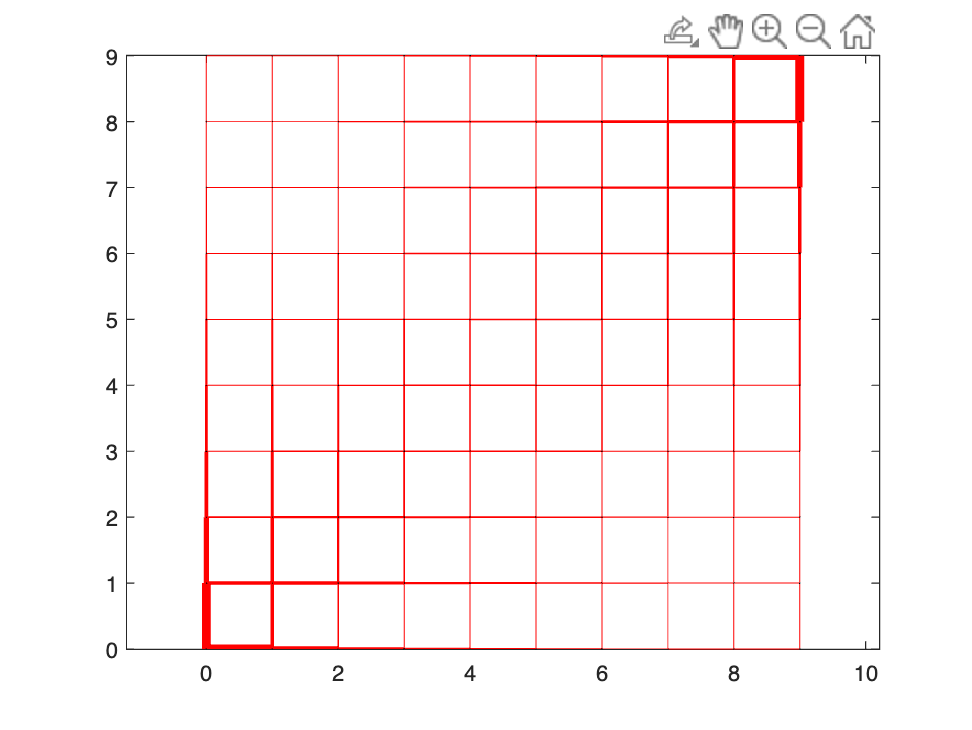

figure; 
hp=plot(x(st)',y(st)','r-');
axis equal

for i=1:length(hp)
   hp(i).LineWidth = max(1e-3,4*abs(X(i))/(max(abs(X)))); 
end
hold on
for i=1:max(max(st)) % ie over nodes
  hr(i)=rectangle('Position',[x(i)-0.005,y(i)-0.005,0.01,0.01],'Curvature',[1 1],'FaceColor',[0 1 0]*(V(i)-min(V))/(max(V)-min(V)));
end

## Exploring the size of N before my computer crashes

Package all the above into a callable function. Function defined with outputs of X,V as above, Vdrop for comparison, and t = time taken to run KirchoffSolve

The following while loop is run calling Kirch_Run() which is the packaged function and the result is plotted with an exponential line of best fit.

% N_plot = [];
% t_plot = [];
% counter = 1;
% N = 4;
% t = 0;
% while t < 10
%     [X,V,t,Vdrop] = Kirch_Run(N);
%     N_plot(counter) = N;
%     t_plot(counter) = t;
%     counter=counter+1;
%     N = N*2;
% end

The t values are plotted against the N values and an exponential fit is calculated:

% g = fittype('a-b*exp(-c*x)');
% f0 = fit(N_plot',t_plot',g,'StartPoint',[0 0 0]);
% xx = linspace(1,max(N_plot),50);
% plot(N_plot,t_plot,'o','DisplayName','Calculated Points');
% hold on
% plot(xx,f0(xx),'r-','DisplayName','Exponential line of Best Fit');
% xlabel("Dimension N")
% ylabel("Time to Compute (s)")
% title("Time Complexity")
% legend()

#### The resulting graph of time complexity for a maximum run time of 120s per iteration

NB: I plotted this in a separate file using all the code above just so I don't run it everytime this script is run.

This is very clearly O(exp(N)) time complexity and so it will very quickly ruin my computer.

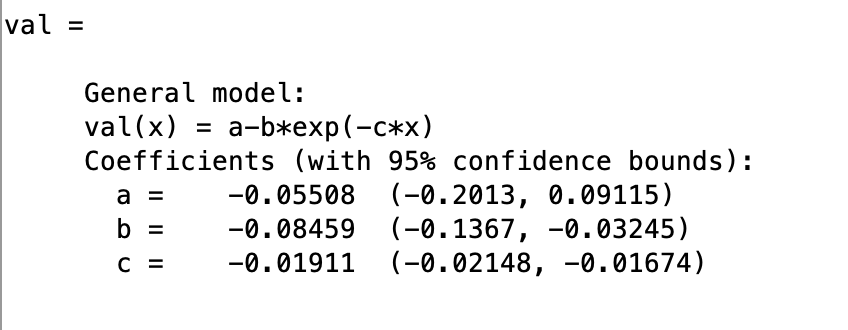

The coefficient of the line of best fit of time are shown above. 

So the time complexity is more accurately: $O\left(0.08\exp(0.02N)\right)$ 

For my computer (2.9Ghz i5 with 8gb ram) to take 1 hour to solve a calculation would only require around 540 variables.

The resistance is plotted as joined up scatter.

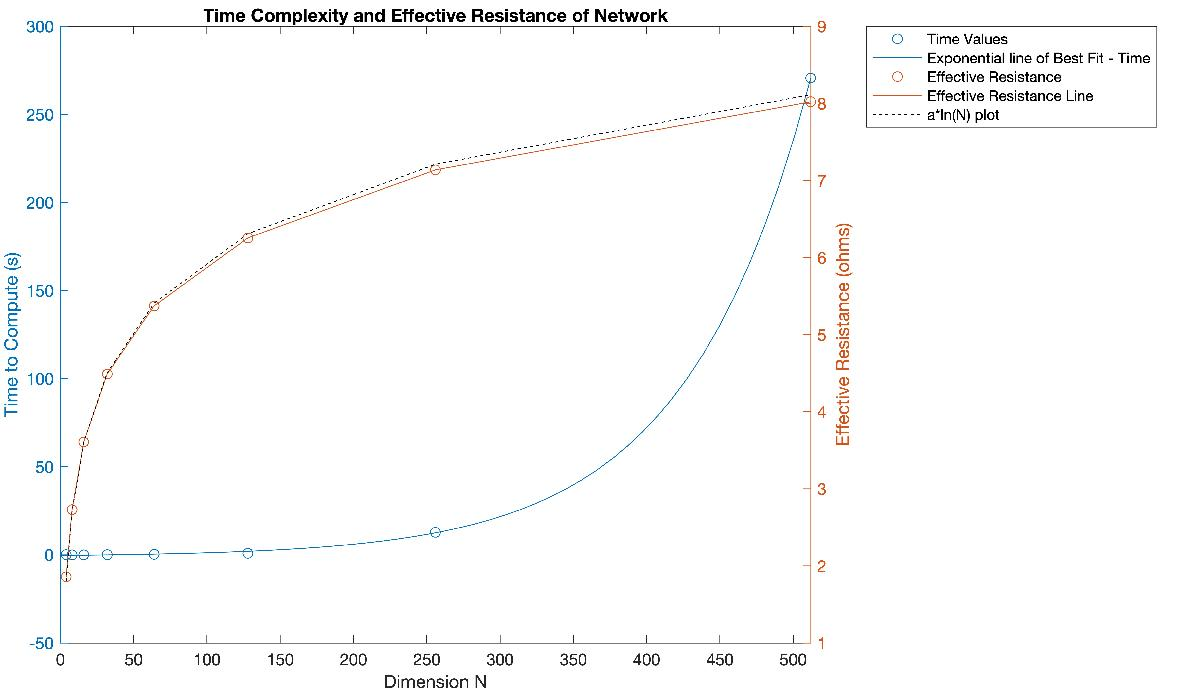

The resistance curve looks suspiciously like an log(N) plot and so I have added a plot of a*ln(N) for comparison with a being a mean of the resistance values/ln(N) for the values plotted.

This suggests that the effective resistance of this sort of network tends towards a value proportional to *a*ln(N)*. With a value of *a *of just under 1.3. This value appears to be a constant related to the shape of the grid. 

The ln(N) shape also suggests that expanding the grid after a certain point produces limited increases in resistance, while the computation increases significantly. By using a predictive formula calculated from a smaller number of dimensions a fairly accurate estimate can be produced for large number N. It is likely logarithmic because as the size of the grid increases the current remains the same and small in the majority of the grid. It is only the area of higher currrent in the start and end corners that slightly increases in size. 